# **Model for simulating a cyclist**

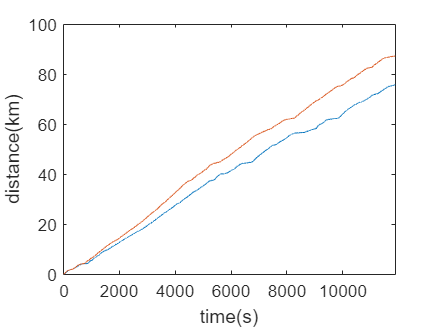

clear 
clc

%%
%basic equation for the resistance calculation
%intitalize values

m_cyclist = 78;
%t = [0:1:5000];
eta = 0.98; % transmission efficiency
m_bike = 7;
g = 9.81;
x = 10e3;
rho = 1.225; %air density
Vg = 0;

%k=0.006; %average slope of the climb
%a = rad2deg(atan(k));

%wind speed and direction
Vw = 2; %positive windspeed as in opposing direction
alpha = 0; %wind incidence
Vw_tan = Vw*cosd(alpha); %tangent vector of the wind speed
Vw_nor = Vw*sind(alpha); %normal vector of the wind speed

Va = Vg-Vw_tan; %airspeed of the cyclist
beta = atan(Vw_nor./Va); %yaw angle
Cd = 0.8; %drag coefficient affected by yaw angle (0.5-0.9)
A = 0.5;  %Frontal area as a function of yaw angle (0.2-0.6) 


%[Pa,Prr,Ppe,Pke,Po] = calculatePower(Vg,rho,Cd,A,m_cyclist,m_bike,a,0);

% loop to iteration power, velocity and acceleration
PInput = 558;
PInputreal = PInput*eta; %the real driving power of the bike------------------------------------

% PInput = [100:0.1:500];
% t = linspace(0,2000,length(PInput));
% vOut = [];

% for pIn = PInputreal
%     vRange = Vg:0.01:300;
%     for i = 2:length(vRange)
%         if (Po > pIn)
%             break;
%         end
%         vNew = vRange(i);
%         dVg = vNew - vRange(i-1);
%         [Pa,Prr,Ppe,Pke,Po] = calculatePower(vNew,rho,Cd,A,m_cyclist,m_bike,a,dVg);
%     end
%     %vOut = [vOut,vNew];
%     Po = 0;
% end



%FEB22
%by importing the routine profile(distance and altitude), any power profile
opts = delimitedTextImportOptions("NumVariables", 9);


% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "position_lat_degrees", "position_long_degrees", "distance", "altitude", "energy", "power", "speed", "cadence"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
testride = readtable("C:\Users\tangj\Desktop\Code\Matlab2\year4\jiaxing\test_ride.csv", opts);
testride = table2array(testride);

%% Clear temporary variables
clear opts
x = testride(:,4);
h = testride(:,5);
V_real = testride(:,8);
X_real = testride(:,4);
W_real = testride(:,6);

n = length(x); %no. of iteration depends on the imported power profile
timeInterval = 1:1:n+1;
Po = testride(:,7); 
Vg = [5];

%could generate a acceleration.velocity and energy profile(with respect to time) 

%load the (generated) distance x(i) VS altitude h(i) file. and the power output file

%estimate and initilize the time intervals(n of iterations), e.g n=7200 for 2 hours

Fw = 0.5;
Crr = 0.01;
W = [0];
X = [0];
Va = [];
Acc = [];

for i = 1:length(h)-1
    aList(i) = real(asin((h(i+1)-h(i))/(x(i+1)-x(i))));
end
aList = [0,aList];

%iteration to obtain the corresponding X,V,W profile
for i=1:n

  a = getVal(x,aList,X(i)); % use piecewise linear interpolation to calculate gradient at each point
  
  Va(i) = Vg(i)-Vw_tan;
  Pa(i) = (0.5*rho*(Va(i)^2)*Cd*A+0.5*rho*Fw*Cd)*Vg(i);
  Prr(i) = (m_bike+m_cyclist)*g*cos(a)*Crr*Vg(i);
  Ppe(i) = (m_bike+m_cyclist)*g*sin(a)*Vg(i);
  Vg(i+1) = real(sqrt((Vg(i)^2)+(1/(m_bike+m_cyclist))*(Po(i)*eta-Pa(i)-Prr(i)-Ppe(i))));
  Acc(i) = Vg(i+1)-Vg(i);   

  W(i+1) = W(i)+Po(i);
  X(i+1) = X(i)+Vg(i);

  if (sum(Vg) >= x(length(x)))
    break;
  end
  i=i+1;
end

%plot---------------------------------------------------------------------
% plot(t,Distance)
Xk = X./1000;  %m to km
X_realk = X_real./1000;
% yyaxis("left")
plot(timeInterval(1:length(timeInterval)),Xk,timeInterval(1:length(timeInterval)-1),X_realk);
xlabel('time(s)');
ylabel('distance(km)'); %------------------distance profile

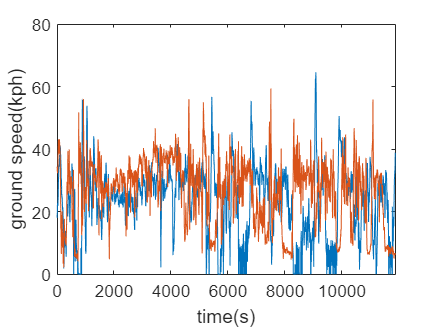


% plot(t,Velocity)
Vgk = Vg.*3.6; %m/s to kph
V_realk = V_real.*3.6;
plot(timeInterval(1:length(timeInterval)),Vgk,timeInterval(1:length(timeInterval)-1),V_realk);
xlabel('time(s)');
ylabel('ground speed(kph)'); %------------------velocity profile

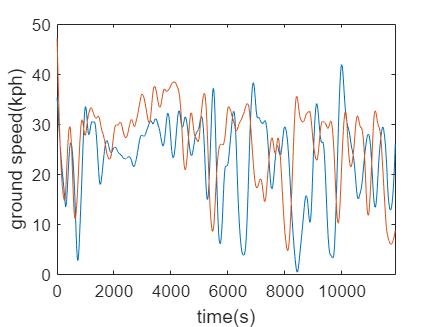

%smoothened
vgkk = smooth(Vgk,0.05,'loess');
vrll = smooth(V_realk,0.05,'loess');
plot(timeInterval(1:length(timeInterval)),vgkk,timeInterval(1:length(timeInterval)-1),vrll);
xlabel('time(s)');
ylabel('ground speed(kph)');

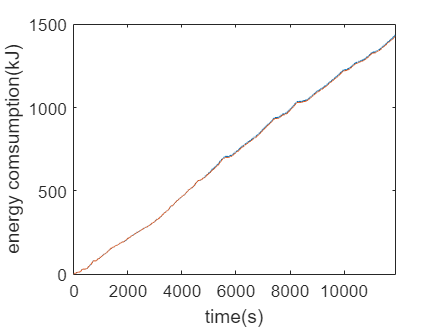



%plot(t,energy)
Wk = W./1000;% J to kJ
W_realk = W_real./1000; 
plot(timeInterval(1:length(timeInterval)),Wk,timeInterval(1:length(timeInterval)-1),W_realk);
xlabel('time(s)');
ylabel('energy comsumption(kJ)'); %------------------energy comsumption

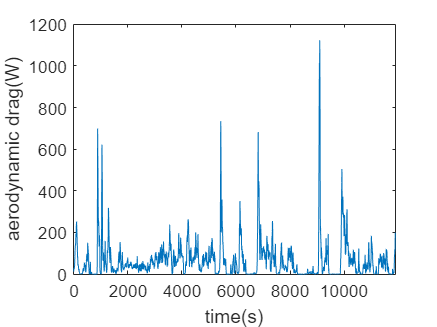


% plot(t,Drag)
plot(timeInterval(1:length(timeInterval)-1),Pa);
xlabel('time(s)');
ylabel('aerodynamic drag(W)'); %------------------drag profile

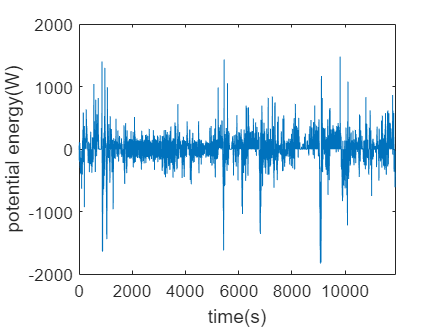


% plot(t,Potential energy)
plot(timeInterval(1:length(timeInterval)-1),Ppe);
xlabel('time(s)');
ylabel('potential energy(W)'); %------------------potential energy profile

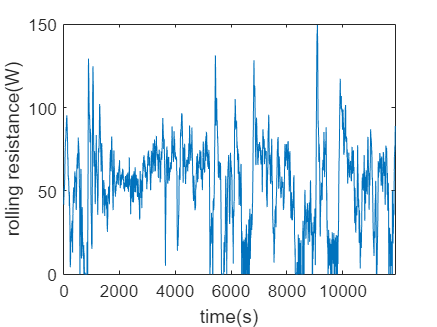


% plot(t,Rolling resistance)
plot(timeInterval(1:length(timeInterval)-1),Prr);
xlabel('time(s)');
ylabel('rolling resistance(W)'); %------------------rolling resistance profile

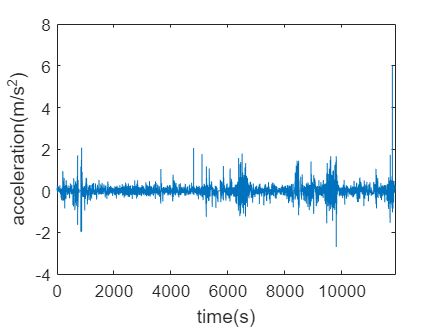



% plot(t,Acceleration)
plot(timeInterval(1:length(timeInterval)-1),Acc);
xlabel('time(s)');
ylabel('acceleration(m/s^2)'); %------------------Acceleration profile

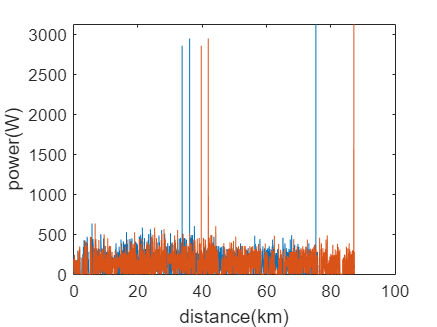




%plot(distance,power)
plot(Xk(1:length(Xk)-1),Po,X_realk(1:length(X)-1),Po);
xlabel('distance(km)');
ylabel('power(W)');

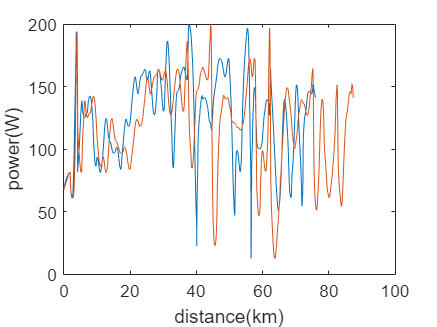

Ps = smooth(Po,0.05,'loess');
%smoothened plot
plot(Xk(1:length(Xk)-1),Ps,X_realk(1:length(X)-1),Ps);
xlabel('distance(km)');
ylabel('power(W)');

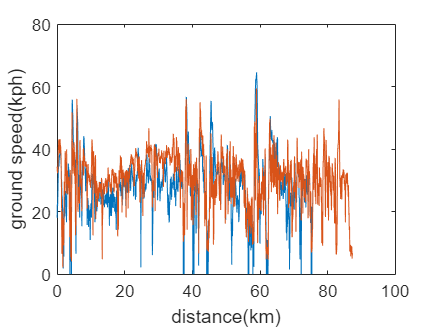



%plot(distance,velocity)
plot(Xk(1:length(Xk)),Vgk,X_realk(1:length(X)-1),V_realk);
xlabel('distance(km)');
ylabel('ground speed(kph)');

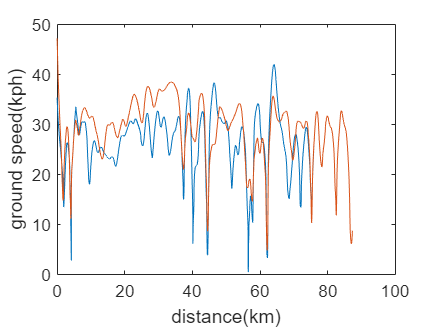

%smoothened plot
plot(Xk(1:length(Xk)),vgkk,X_realk(1:length(X)-1),vrll);
xlabel('distance(km)');
ylabel('ground speed(kph)');


time_real = i/60;
disp('real time used is');

real time used is



disp('estimated time is');

estimated time is



%plot the relation between velocity and the power

% yyaxis("left")
% plot(t, vOut);
% ylabel('ground velocity(m/s)')
% xlabel('time(s)')
% hold on
% yyaxis("right")
% plot(t, PInput);
% ylabel('Power(W)')




%Visulization of various drags at different velocities
%Visulization of energy consumption
%Visulization of power output phase

function [Pa,Prr,Ppe,Pke,Po] = calculatePower(Vg,rho,Cd,A,m_cyclist,m_bike,a,dVg)
    g = 9.81;
    Vw = 1; %positive windspeed as in opposing direction
    alpha = 10; 
    Vw_tan = Vw*cosd(alpha);
    Vw_nor = Vw*sind(alpha);
    Va = Vg-Vw_tan;
    
    %%Power calculation
    %Aero drag
    %Translational
    Dt = 0.5.*rho.*(Va.^2).*Cd.*A;
    Pt = Dt.*Vg;
    
    %Rotational
    Fw = 0.5; %rotational drag coefficient 
    Dr = 0.5*rho*Fw*Cd;
    Pr = Dr.*Vg;
    
    Pa = Pt+Pr; %total aero drag
    
    %Rolling resistance
    Crr = 0.01; %rolling resistance coefficient(effected by contact characteristic) 
    Frr = (m_cyclist+m_bike)*g*cosd(a)*Crr;
    Prr = Frr.*Vg;
    
    %potential engergy
    Ppe = (m_cyclist+m_bike).*g.*Vg.*sind(a);
    
    %% kinetic energy
    %Translational
    Pket = 0.5.*(m_cyclist+m_bike).*(dVg.^2);
    %Rotational
    domega = dVg./0.32; %angular velocity of the wheel
    If = 0.034; %moment of inertia of the front wheel calculated from estimated typial front wheel profile for a 50mm depth rim
    Ir = 0.036; %moment of inertia of the rear wheel calculated from estimated typial rear wheel profile for a 50mm depth rim
    Pker = 0.5*(If+Ir)*domega.^2;
    Pke = Pket+Pker;
    % power output modification
   
    Po = Pa + Prr + Ppe + Pke;
end


function a = getVal(list1,list2,xVal)
    list1 = [0;list1];
    list2 = [list2(1),list2];
    for i = 1:length(list1) - 1
        if (xVal >= list1(i) && xVal < list1(i+1))
            a = (list2(i+1) - list2(i))/(list1(i+1)-list1(i)) * (xVal - list1(i)) + list2(i);
            break;
        end
    end
end



## Whats next 2.22 :

- add draft estimation in the model

- add boundary conditions (total energy consumption)

- add internal BCs (brake at some point for a speed limit)